# SAGE Automated Data Retrieval Options

This file reviews options for automatically retrieving, saving, loading, and/or plotting seismometer data stored on SAGE's website (formerly Iris). These workflows rely on SAGE's [FDSN](http://www.fdsn.org/webservices/) web service for data management.

## Programmatic retrieval of metadata from Wilber

Wilber 3 allows users to interactively specify events of interest to retrieve. Event metadata can also be programmatically retrieved by MATLAB because each data set is retrieved from a URL that the interactive interface generates behind the scenes.

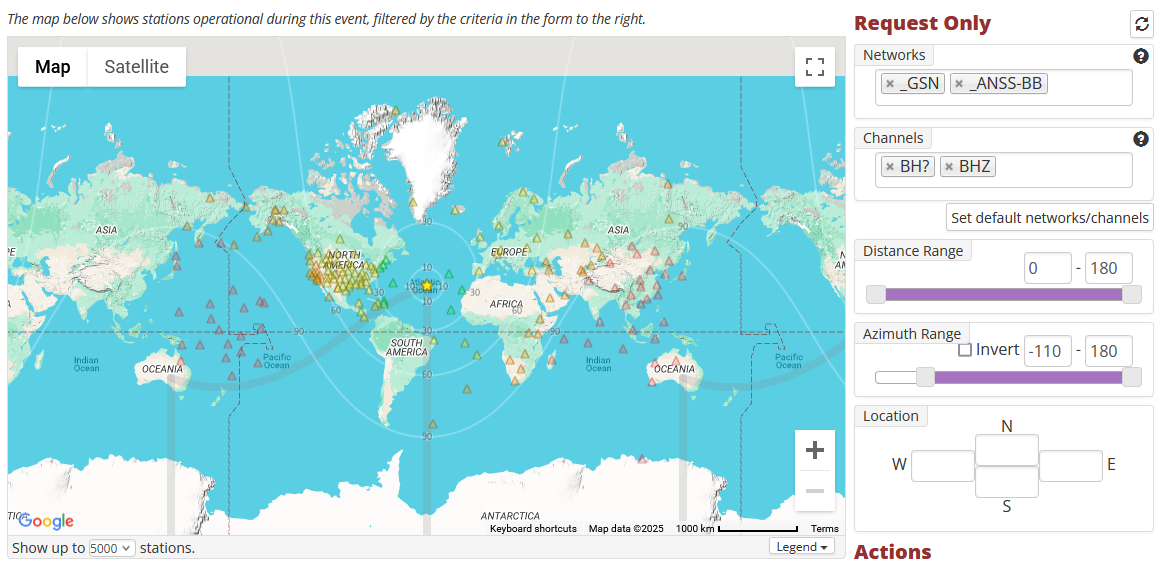

NSF SAGE Wilber 3: Select Event. (2025, February 19). "Services implementation: FDSNWS". [https://ds.iris.edu/wilber3/find_event](https://ds.iris.edu/wilber3/find_event) 

A table of event metadata can be saved as a .csv file or opened directly in MATLAB with [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html).

myurl = 'https://service.iris.edu/fdsnws/event/1/query?starttime=2025-01-08&endtime=2025-02-07T23%3A59%3A59.999999&minmagnitude=5.1&maxmagnitude=10&mindepth=0&maxdepth=6371&limit=10000&output=text';

% save the file
websave('wilbermetadata.csv',myurl);
% readtable directly
event_table_wil = readtable(myurl)

## Programmatic retrieval of data using FDSN Web Services

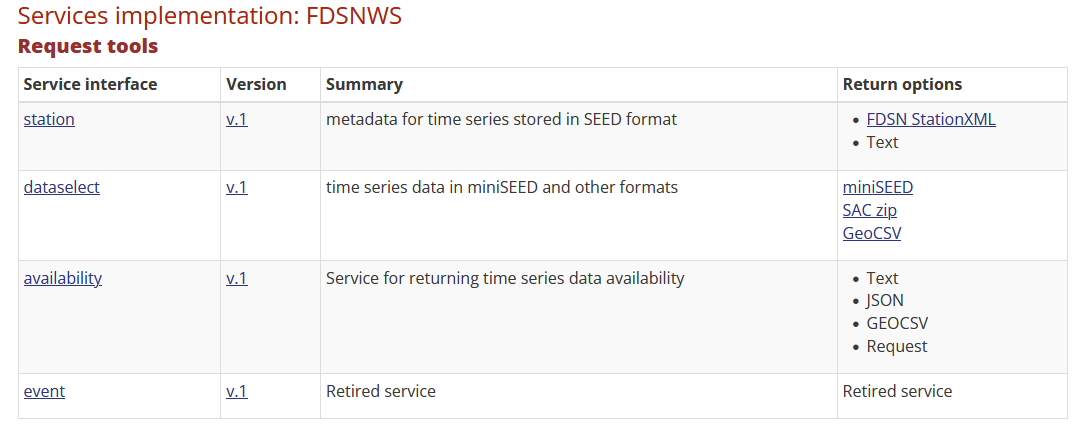

NSF SAGE Facility Web Services. (2025, February 14). "Services implementation: FDSNWS". [https://service.iris.edu/fdsnws/](https://service.iris.edu/fdsnws/)

### Station - Metadata

Station metadata can be retrieved here without the Wilber 3 interface. 

% read the metadata file directly
% Can use GEOCSV or text. Using "station xml" requires a helper function
% to parse data from xmlread into a structure
dataURL = 'https://service.iris.edu/fdsnws/station/1/query?sta=ANMO&cha=BH*&level=channel&format=text&includecomments=true&nodata=404';
metadata1 = readtable(dataURL)

% save the metadata file
websave('StationMetaData',dataURL);

### Dataselect - Time Series Data

Time series data can be retrieved in three primary formats, reviewed below. These workflows save data from a FDSN URL on your local device. To build the appropriate URL, **SAGE provides a URL builder: **[**https://service.earthscope.org/fdsnws/dataselect/docs/1/builder/**](https://service.earthscope.org/fdsnws/dataselect/docs/1/builder/) 

When you've specified your parameters and generated the appropriate URL, substitute it into any of the below workflows as the dataURL.

#### SAC Format

dataURL = 'https://service.iris.edu/fdsnws/dataselect/1/query?sta=ANMO&cha=BHZ&starttime=2025-02-06T00:00:00&endtime=2025-02-06T02:00:00&format=sac.zip&nodata=404';

if ~exist('DataFolder','dir')
    mkdir('DataFolder')% create DataFolder
end
addpath('DataFolder')

% download and unzip the saved file
unzip(dataURL,'DataFolder')

% load the SAC file using rdsac and/or Laura's helper function
% https://www.mathworks.com/matlabcentral/fileexchange/46356-rdsac-and-mksac-read-and-write-sac-seismic-data-file?s_tid=ta_fx_results
% list SAC files in current directory
cd('DataFolder')

sacfiles = dir('*.SAC');
n = length(sacfiles);

% Use rdsac to read in all files from above list
for ii = 1:n
    TimeSeries(ii) = rdsac(sacfiles(ii).name); 
end

% HOW RDSAC MAKES THE TIME VECTOR:
% DateNumber = datenum(t) converts the datetime or duration values in the 
% input array t to serial date numbers. A serial date number represents the 
% whole and fractional number of days from a fixed, preset date (January 0, 0000) 
% in the proleptic ISO calendar. To convert back to a datetime format, do
% the following:
%    myDate =
%    datetime(TimeSeries(ii).t,'ConvertFrom','datenum','Format',...
%    'yyyy-MM-dd HH:mm:ss.SSS);

% convert structure S.d to an array for ease of use in future
station = zeros(length(TimeSeries(1).d),n);

% converting the data from a structure to an array so that 'stackedplot' can
% be called later on
dt = meta_data.DELTA(1,1); % time step between each sampling index. 1/frequency

% Each SAC file has a "t" vector associated with it to mark time. Time is
% measured as "seconds since
 
for ii = 1:n
    x = length(TimeSeries(ii).d);
    station(1:x,ii) = TimeSeries(ii).d;
    timetable(:,ii) = datetime(TimeSeries(ii).t,'ConvertFrom','datenum','Format', 'yyyy-MM-dd HH:mm:ss.SSS');
end

figure
plot(timetable(:,2),station(:,2)) % Column 2 in station
title('SAC file data from Station 2 data');
ylabel('Amplitude');
% legend('1', '2')

cd .. % back up to above DataFolder level

#### GeoCSV Format

dataURL = 'https://service.iris.edu/fdsnws/dataselect/1/query?sta=ANMO&cha=BHZ&starttime=2025-02-06T00:00:00&endtime=2025-02-06T02:00:00&format=geocsv.zip&nodata=404';
% TimeSeries = readtable(dataURL)% CANNOT READ GEOCSV DIRECTLY!!

% download and unzip the saved file
if ~exist('DataFolder','dir')
    mkdir('DataFolder')% create DataFolder
end
addpath('DataFolder')


unzip(dataURL,'DataFolder')

Error using matlab.io.internal.archive.checkFilename>downloadArchiveFile (line 81)
Function UNZIP was unable to read URL ''https://service.iris.edu/fdsnws/dataselect/1/query?sta=ANMO&cha=BHZ&starttime=2025-02-06T00:00:00&endtime=2025-02-06T02:00:00&format=geocsv.zip&nodata=404''.

Error in <a href="matlab:matlab.lang.internal.introspective.errorDocCallback('matlab.io.internal.archive.checkFilename', 'C:\Program Files\MATLAB\R2025b\toolbox\matlab\io\archive\+matlab\+io\+internal\+archive\checkFilename.m', 51)" style="font-weight:bold">matlab.io.internal.archive.checkFilename</


geofiles = dir('*.csv');
n = length(geofiles);

% Use rdsac to read in all files from above list
for ii = 1:n
    TimeSeries = GeoCSVimport(geofiles(ii).name); % helper function generated from Import Tool
end


% Plot the Samples 
% Can we also show real times on the X axis?
plot(TimeSeries.Sample(:)) 
title('GEOCSV file data from Sample data column');
ylabel('Amplitude');

#### MiniSeed Format

% save a miniseed file
dataURL = 'https://service.iris.edu/fdsnws/dataselect/1/query?sta=ANMO&cha=BHZ&starttime=2025-02-06T00:00:00&endtime=2025-02-06T02:00:00&format=mseed&nodata=404';

% download and unzip the saved file
% download and unzip the saved file
if ~exist('DataFolder','dir')
    mkdir('DataFolder')% create DataFolder
end
addpath('DataFolder')

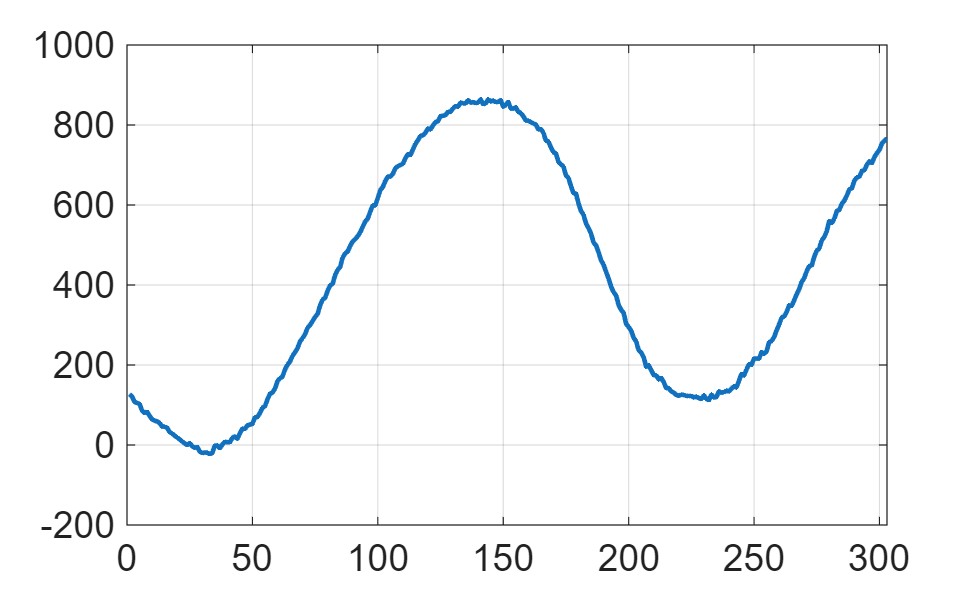


websave('MySeedData.mseed',dataURL);

% load the miniSEED file using rdmseed
% https://www.mathworks.com/matlabcentral/fileexchange/28803-rdmseed-and-mkmseed-read-and-write-miniseed-files
seedfiles = dir('*.mseed');
n = length(seedfiles);

% Use rdsac to read in all files from above list
for ii = 1:n
    seed_TimeSeries(ii).file = rdmseed(seedfiles(ii).name); 
end


figure
plot(seed_TimeSeries(1).file(1).d)

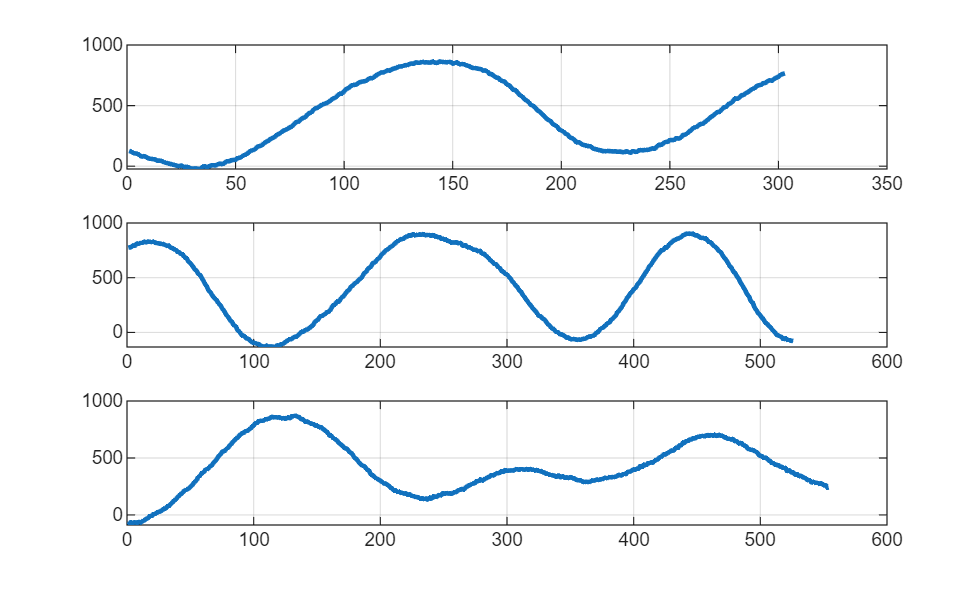


% figure
% plot(seed_TimeSeries.file(1).t, seed_TimeSeries.file(1).d) 
% title('miniSEED data from "d" column for times "t"');
% ylabel('Amplitude');

% a second plot option
figure
tiledlayout(3,1)
nexttile
plot(seed_TimeSeries(1).file(1).d);
nexttile
plot(seed_TimeSeries(1).file(2).d)
nexttile
plot(seed_TimeSeries(1).file(3).d)


cd .. % back up to above DataFolder level

### Availability

For returning the time series data availability reports, the same workflow can be used as is used for the meta data retrieval, just swapping out the appropriate URL. File type can be text, json, or geocsv.

Helper Functions

function [table] = GeoCSVimport(filename, dataLines)
%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [20, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Time", "Sample"];
opts.VariableTypes = ["string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Time", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Time", "EmptyFieldRule", "auto");

% Import the data
table= readtable(filename, opts);

end